# This code plots the data as shown in Figure 5

Kristen Fogaren [fogaren@bc.edu](mailto:fogaren@bc.edu)

Assumes the data has been downloaded using M2M_Data_Figure5.m and saved 

cmocean package needs to be installed [http://matplotlib.org/cmocean](http://matplotlib.org/cmocean)

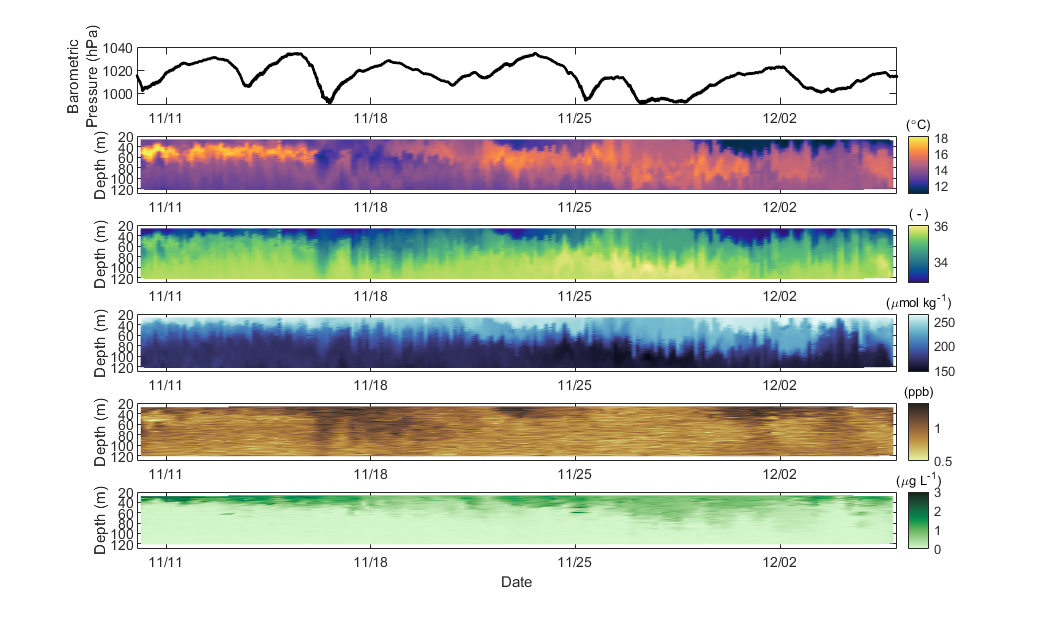

load CP03ISSMmetpackage
load CP02PMCOProfilerCTD
load CP02PMCOProfilerDO
load CP02PMCOProfilerFLORT
 
% Time period of interest, data files include all of 2018 
startdt = datenum(2018,11,10); 
enddt = datenum(2018,12,06); 

% Finds the time period of interst in all 4 sets of data 
% CTD 
dt = ctd_mtime;
ind = find(dt > startdt);
dt1 = ind(1);

ind = find(dt < enddt);
dt2 = ind(end);

% FLORT 
FLdt = flort_mtime;
ind = find(FLdt > startdt);
FLdt1 = ind(1);

ind = find(FLdt < enddt);
FLdt2 = ind(end);

% METBK
MTdt = metbk_mtime;
ind = find(MTdt > startdt);
MTdt1 = ind(1);

ind = find(MTdt < enddt);
MTdt2 = ind(end);

% DO
DOdt = DO_mtime;
ind = find(DOdt > startdt);
DOdt1 = ind(1);

ind = find(DOdt < enddt);
DOdt2 = ind(end);

% Convert pressure (db) to depth (m)
lat = 40.10123; %Latitude in degrees % ***
% The gravity variation with latitude and pressure is computed as:
x = (sin(lat/57.29578)).^2;
pCTD = ctd_variables(5).data;
pFL = flort_variables(7).data;
gCTD = 9.780318*(1.0 + (5.2788e-3 + 2.36e-5*x)*x) + 1.092e-6.*pCTD;
gFL = 9.780318*(1.0 + (5.2788e-3 + 2.36e-5*x)*x) + 1.092e-6.*pFL;
ctd_zm = (((((-1.82e-15.*pCTD + 2.279e-10 ).*pCTD - 2.2512e-5 ).*pCTD + 9.72659).*pCTD)./ gCTD);
fl_zm = (((((-1.82e-15.*pFL + 2.279e-10 ).*pFL - 2.2512e-5 ).*pFL + 9.72659).*pFL)./ gFL);

% Creates a meshgrid delt by delz and does interp
delt = 3/24; % Time step
delz = 1.5; % Depth interval
interpmethod = 'linear'; %linear, natural, nearest

% Meshgrid from dt1:dt2 every delt interval
% and from 25 m to 125 m at delz intervals
% Same grid for temp/sal/DO
[xq,yq] = meshgrid(ctd_mtime(dt1):delt:ctd_mtime(dt2),25:delz:125);
% Same grid for CDOM and FL
[FLxq,FLyq] = meshgrid(flort_mtime(FLdt1):delt:flort_mtime(FLdt2),25:delz:125);

% Grids desired data on mesh
tempq = griddata(ctd_mtime(dt1:dt2),ctd_zm(dt1:dt2),ctd_variables(2).data(dt1:dt2),xq,yq,interpmethod);
salq = griddata(ctd_mtime(dt1:dt2),ctd_zm(dt1:dt2),ctd_variables(3).data(dt1:dt2),xq,yq,interpmethod);
DOq = griddata(ctd_mtime(dt1:dt2),ctd_zm(dt1:dt2),DO_variables(2).data(dt1:dt2),xq,yq,interpmethod);
CDOMq = griddata(flort_mtime(FLdt1:FLdt2),fl_zm(FLdt1:FLdt2),flort_variables(4).data(FLdt1:FLdt2),FLxq,FLyq,interpmethod);
FLq = griddata(flort_mtime(FLdt1:FLdt2),fl_zm(FLdt1:FLdt2),flort_variables(3).data(FLdt1:FLdt2),FLxq,FLyq,interpmethod);

figure
fig = gcf;
set(fig, 'Color', 'w');
set(fig,'units','inches','position',[.5 .5 11 6.5])
set(0,'defaultaxesfontsize',13);
set(0,'defaulttextfontsize',13);
ax1 = subplot(611);
plot(metbk_mtime(MTdt1:MTdt2),metbk_variables(7).data(MTdt1:MTdt2),'.k')
xlim([metbk_mtime(MTdt1) metbk_mtime(MTdt2)])
datetick('x','keeplimits')
ylabel({'Barometric';'Pressure (hPa)'},'FontName','Arial')
c = colorbar;
ylim([990 1040]) 
c.Visible = 'off';

ax2 = subplot(612);
h = pcolor(ctd_mtime(dt1):delt:ctd_mtime(dt2),25:delz:125,tempq);
set(h,'EdgeColor','none')
c=colorbar;
cmocean('thermal')
shading interp
title(c,ctd_variables(2).units)
title(c,'(\circC)')
set(gca, 'YDir','reverse')
ylabel('Depth (m)')
xlim([ctd_mtime(dt1) ctd_mtime(dt2)])
ylim([20 130])
datetick('x','KeepLimits')
box on

ax3 = subplot(613);
h = pcolor(ctd_mtime(dt1):delt:ctd_mtime(dt2),25:delz:125,salq);
set(h,'EdgeColor','none')
c=colorbar;
cmocean('haline')
shading interp
title(c,ctd_variables(3).units)
title(c,'( - )')
set(gca, 'YDir','reverse')
ylabel('Depth (m)')
xlim([ctd_mtime(dt1) ctd_mtime(dt2)])
ylim([20 130])
datetick('x','KeepLimits')
box on

ax4 = subplot(614);
h = pcolor(ctd_mtime(dt1):delt:ctd_mtime(dt2),25:delz:125,DOq);
set(h,'EdgeColor','none')
c=colorbar;
cmocean('ice')
shading interp
title(c,DO_variables(2).units)
title(c,'(\mumol kg^-^1)')
set(gca, 'YDir','reverse')
ylabel('Depth (m)')
xlim([DO_mtime(DOdt1) DO_mtime(DOdt2)])
ylim([20 130])
datetick('x','KeepLimits')
box on

ax5 = subplot(615);
h = pcolor(flort_mtime(FLdt1):delt:flort_mtime(FLdt2),25:delz:125,CDOMq);
set(h,'EdgeColor','none')
c=colorbar;
cmocean('turbidity')
shading interp
title(c,flort_variables(4).units)
title(c,'(ppb)')
set(gca, 'YDir','reverse')
ylabel('Depth (m)')
xlim([flort_mtime(FLdt1) flort_mtime(FLdt2)])
ylim([20 130])
datetick('x','KeepLimits')
box on

ax6 = subplot(616);
h = pcolor(flort_mtime(FLdt1):delt:flort_mtime(FLdt2),25:delz:125,FLq);
set(h,'EdgeColor','none')
caxis([0 3])
c=colorbar;
cmocean('algae')
shading interp
title(c,flort_variables(3).units)
title(c,'(\mug L^-^1)')
set(gca, 'YDir','reverse')
ylabel('Depth (m)')
xlim([flort_mtime(FLdt1) flort_mtime(FLdt2)])
ylim([20 130])
datetick('x','KeepLimits')
box on
xlabel('Date')
grid on
linkaxes([ax1 ax5 ax4 ax3 ax2 ax2 ax6],'x')